% Load your RGB image
rgbImage = imread('Y50.png')

rgbImage = 636×219×3 uint8 array
rgbImage(:,:,1) =

   228   190   154   160   194   203   192   198   209   207   202   199   196   195   200   204   209   206   203   185   160   155   196   229   229   233   234   235   236   236   236   236   237   237   237   237   237   237   237   235   236   235   236   236   235   234   233   235   235   236   235   236   237   236   236   235   234   234   234   235   237   236   235   235   234   234   235   235   236   236   235   235   235   235   237   236   236   236   236   235   235   235   235   236   236   236   236   237   236   237   236   236   236   236   235   235   235   235   235   236   235   235   237   236   237   238   238   238   238   237   236   235   234   235   235   233   233   235   236   237   237   236   236   237   239   238   238   238   237   237   237   236   234   234   235   236   238   238   238   237   237   237   238   238   239   238   236   235   234   234   235   235   234   234   236   237   237   237

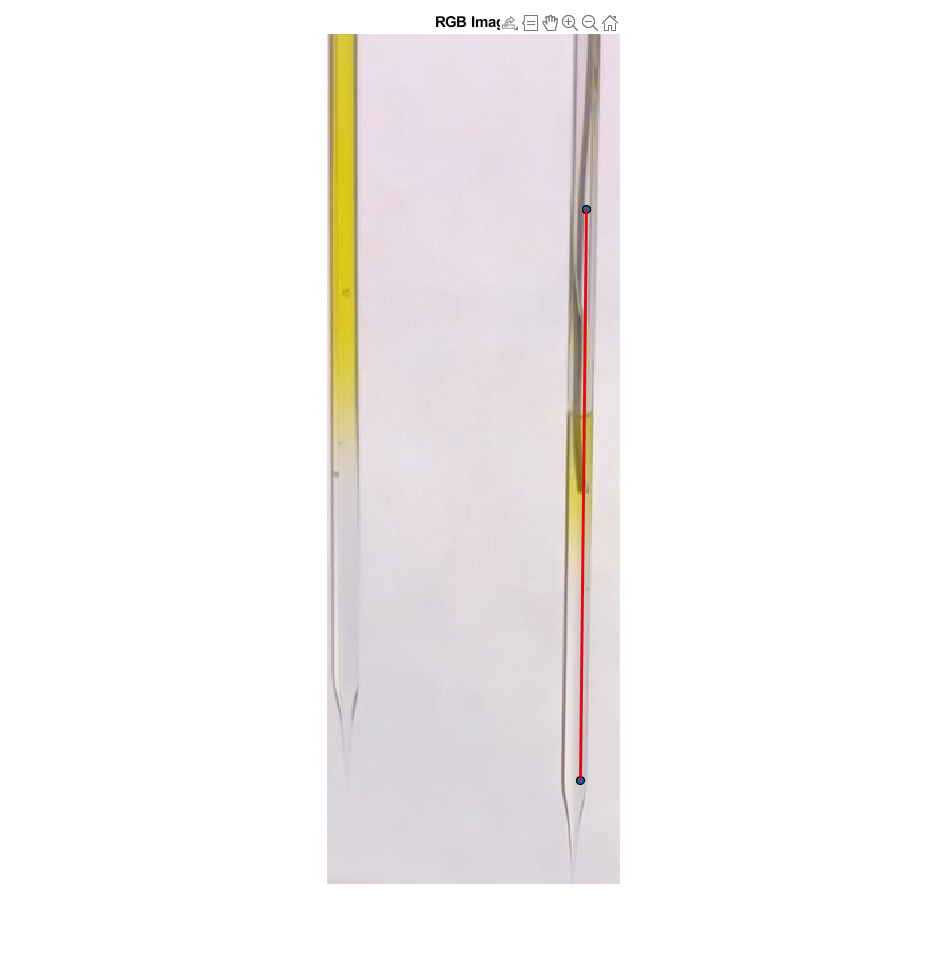

% Display the RGB image
imshow(rgbImage);
title('RGB Image');

% Use the drawline function to interactively draw a line on the image
h = drawline;

% Get the coordinates of the drawn line
line_coordinates = h.Position;

% Display the drawn line on the image
hold on;
plot(line_coordinates(:,1), line_coordinates(:,2), 'r', 'LineWidth', 2);
hold off;


% Save the line coordinates to a MAT file
save('Y50_line', 'line_coordinates');

